
load long_modem_rx.mat

% The received signal includes a bunch of samples from before the
% transmission started so we need discard these samples that occurred before
% the transmission started. 

start_idx = find_start_of_signal(y_r,x_sync);

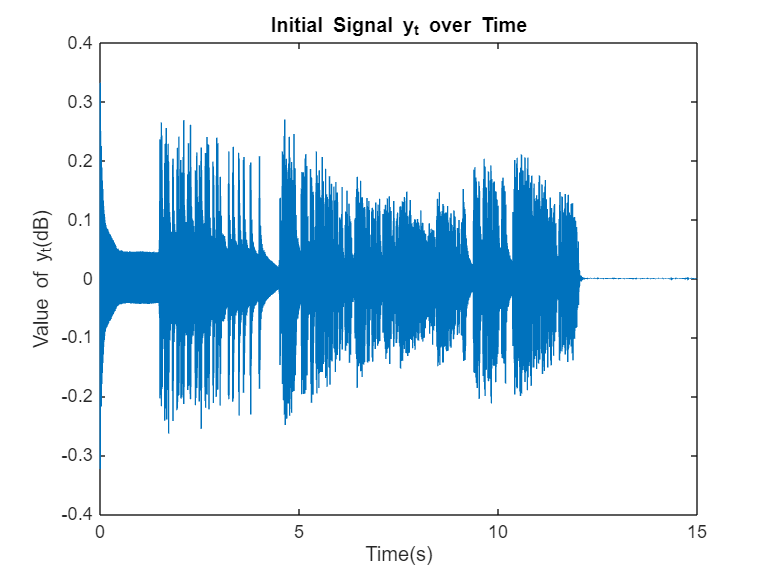

% start_idx now contains the location in y_r where x_sync begins
% we need to offset by the length of x_sync to only include the signal
% we are interested in
y_t = y_r(start_idx+length(x_sync):end); % y_t is the signal which starts at the beginning of the transmission


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%  Put your decoder code here
t = (0:length(y_t)-1)'/Fs; 
plot(t, y_t)
title("Initial Signal y_t over Time")
xlabel("Time(s)")
ylabel("Value of y_t(dB)")

X = 1.0e+02 *

  -0.0007 - 0.0016i
   0.0009 - 0.0047i
   0.0040 + 0.0016i
  -0.0054 + 0.0010i
  -0.0032 - 0.0023i
   0.0037 + 0.0009i
  -0.0023 + 0.0021i
  -0.0022 - 0.0005i
   0.0047 - 0.0011i
  -0.0022 + 0.0047i


f = 1.0e+04 *

   -2.5736   -2.5736   -2.5735   -2.5735   -2.5734   -2.5734   -2.5733   -2.5733   -2.5733   -2.5732   -2.5732   -2.5731   -2.5731   -2.5730   -2.5730   -2.5730   -2.5729   -2.5729   -2.5728   -2.5728   -2.5728   -2.5727   -2.5727   -2.5726   -2.5726   -2.5725   -2.5725   -2.5725   -2.5724   -2.5724   -2.5723   -2.5723   -2.5723   -2.5722   -2.5722   -2.5721   -2.5721   -2.5720   -2.5720   -2.5720   -2.5719   -2.5719   -2.5718   -2.5718   -2.5717   -2.5717   -2.5717   -2.5716   -2.5716   -2.5715


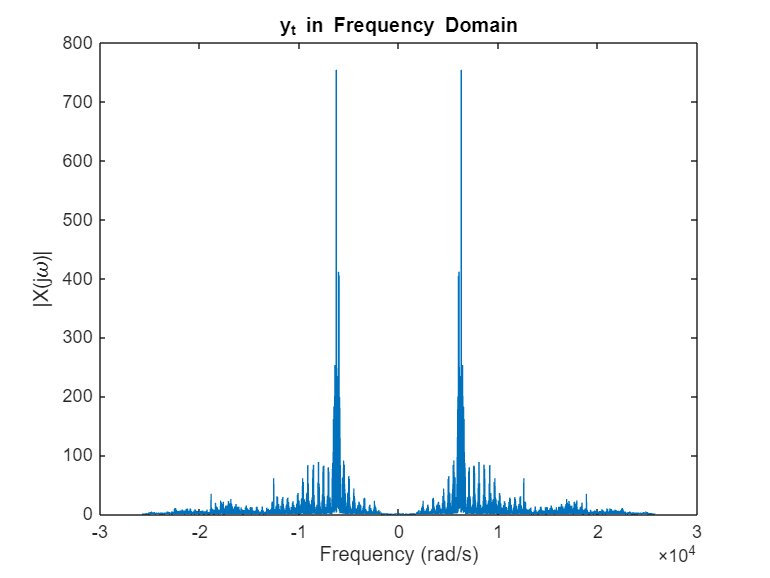

f = 1.0e+04 *

   -2.5736   -2.5736   -2.5735   -2.5735   -2.5734   -2.5734   -2.5733   -2.5733   -2.5733   -2.5732   -2.5732   -2.5731   -2.5731   -2.5730   -2.5730   -2.5730   -2.5729   -2.5729   -2.5728   -2.5728   -2.5728   -2.5727   -2.5727   -2.5726   -2.5726   -2.5725   -2.5725   -2.5725   -2.5724   -2.5724   -2.5723   -2.5723   -2.5723   -2.5722   -2.5722   -2.5721   -2.5721   -2.5720   -2.5720   -2.5720   -2.5719   -2.5719   -2.5718   -2.5718   -2.5717   -2.5717   -2.5717   -2.5716   -2.5716   -2.5715


X = 1.0e+02 *

  -0.0007 - 0.0016i
   0.0009 - 0.0047i
   0.0040 + 0.0016i
  -0.0054 + 0.0010i
  -0.0032 - 0.0023i
   0.0037 + 0.0009i
  -0.0023 + 0.0021i
  -0.0022 - 0.0005i
   0.0047 - 0.0011i
  -0.0022 + 0.0047i



[f, X] = make_frequency_domain_plot(Fs, y_t, "y_t")

soundsc(y_t, Fs)

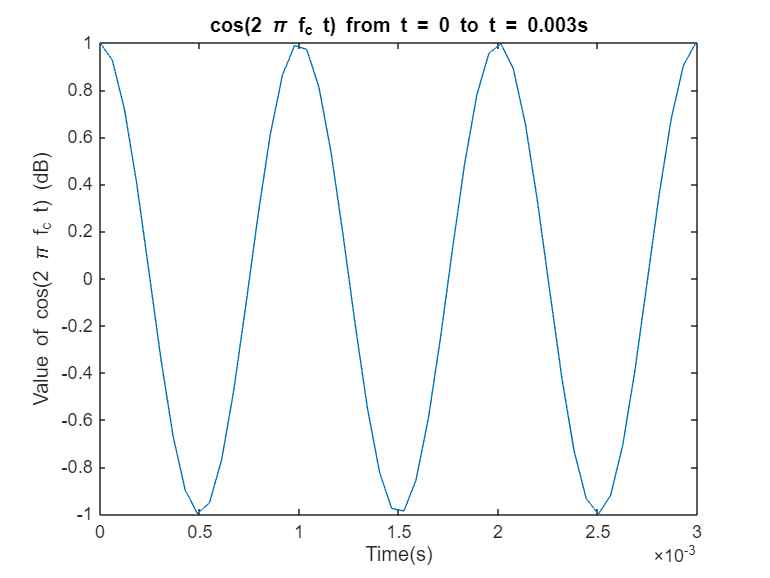


%% 
t_special = (0:length(y_t)-1)'/(Fs*2); 
cosinewave = cos(2*pi*f_c*t);
cosinewave_special = cos(2*pi*f_c*t_special);
plot(t_special(1:50), cosinewave_special(1:50))
title("cos(2 \pi f_c t) from t = 0 to t = 0.003s")
xlabel("Time(s)")
ylabel("Value of cos(2 \pi f_c t) (dB)")

X = 1.0e+04 *

  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i


f = 1.0e+04 *

   -2.5736   -2.5736   -2.5735   -2.5735   -2.5734   -2.5734   -2.5733   -2.5733   -2.5733   -2.5732   -2.5732   -2.5731   -2.5731   -2.5730   -2.5730   -2.5730   -2.5729   -2.5729   -2.5728   -2.5728   -2.5728   -2.5727   -2.5727   -2.5726   -2.5726   -2.5725   -2.5725   -2.5725   -2.5724   -2.5724   -2.5723   -2.5723   -2.5723   -2.5722   -2.5722   -2.5721   -2.5721   -2.5720   -2.5720   -2.5720   -2.5719   -2.5719   -2.5718   -2.5718   -2.5717   -2.5717   -2.5717   -2.5716   -2.5716   -2.5715


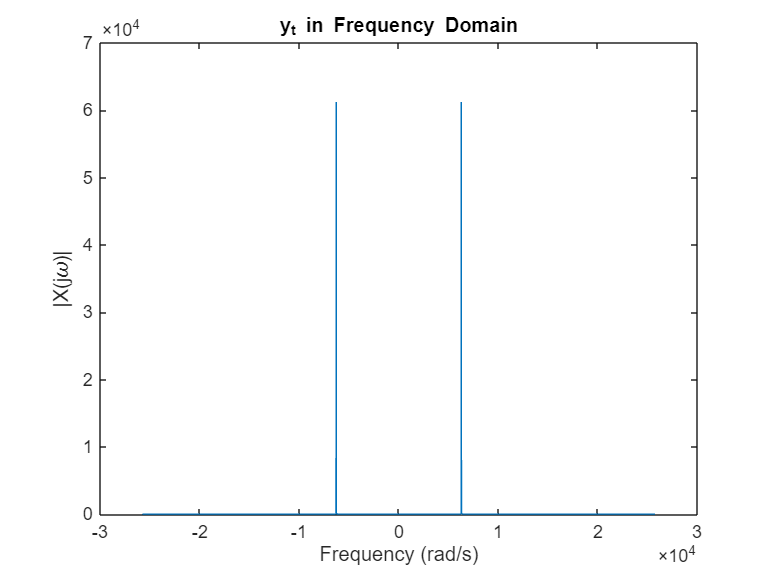

f = 1.0e+04 *

   -2.5736   -2.5736   -2.5735   -2.5735   -2.5734   -2.5734   -2.5733   -2.5733   -2.5733   -2.5732   -2.5732   -2.5731   -2.5731   -2.5730   -2.5730   -2.5730   -2.5729   -2.5729   -2.5728   -2.5728   -2.5728   -2.5727   -2.5727   -2.5726   -2.5726   -2.5725   -2.5725   -2.5725   -2.5724   -2.5724   -2.5723   -2.5723   -2.5723   -2.5722   -2.5722   -2.5721   -2.5721   -2.5720   -2.5720   -2.5720   -2.5719   -2.5719   -2.5718   -2.5718   -2.5717   -2.5717   -2.5717   -2.5716   -2.5716   -2.5715


X = 1.0e+04 *

  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i




[f, X] = make_frequency_domain_plot(Fs, cosinewave, "y_t")

soundsc(cosinewave, Fs)

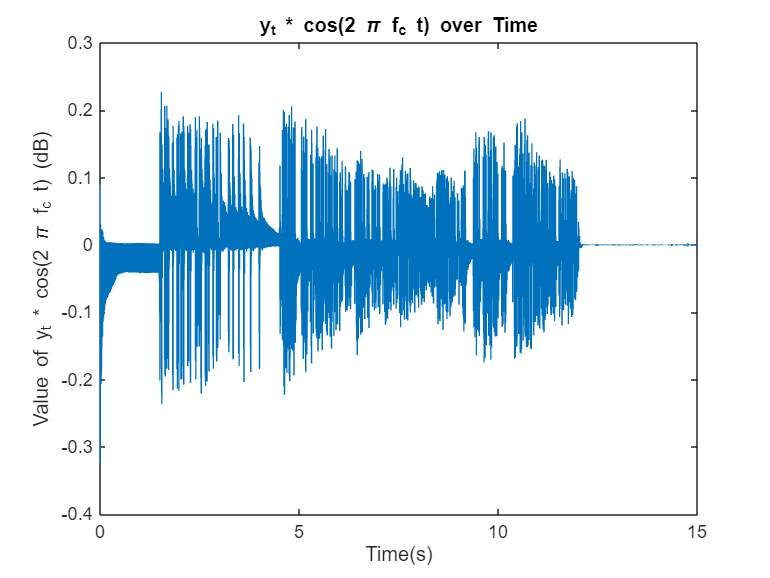

%% 

x_d = y_t .* cosinewave; 
plot(t, x_d)
title("y_t * cos(2 \pi f_c t) over Time")
xlabel("Time(s)")
ylabel("Value of y_t * cos(2 \pi f_c t) (dB)")

X = 1.0e+02 *

   0.0127 - 0.0134i
  -0.0136 + 0.0057i
   0.0003 - 0.0096i
   0.0096 + 0.0110i
   0.0013 + 0.0022i
  -0.0071 - 0.0176i
   0.0022 + 0.0056i
  -0.0031 + 0.0097i
  -0.0027 + 0.0085i
   0.0151 - 0.0040i


f = 1.0e+04 *

   -2.5736   -2.5736   -2.5735   -2.5735   -2.5734   -2.5734   -2.5733   -2.5733   -2.5733   -2.5732   -2.5732   -2.5731   -2.5731   -2.5730   -2.5730   -2.5730   -2.5729   -2.5729   -2.5728   -2.5728   -2.5728   -2.5727   -2.5727   -2.5726   -2.5726   -2.5725   -2.5725   -2.5725   -2.5724   -2.5724   -2.5723   -2.5723   -2.5723   -2.5722   -2.5722   -2.5721   -2.5721   -2.5720   -2.5720   -2.5720   -2.5719   -2.5719   -2.5718   -2.5718   -2.5717   -2.5717   -2.5717   -2.5716   -2.5716   -2.5715


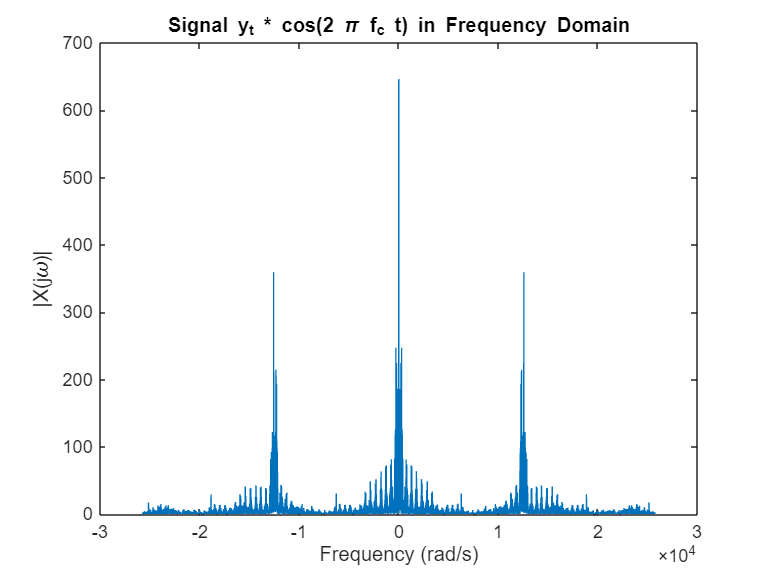

f = 1.0e+04 *

   -2.5736   -2.5736   -2.5735   -2.5735   -2.5734   -2.5734   -2.5733   -2.5733   -2.5733   -2.5732   -2.5732   -2.5731   -2.5731   -2.5730   -2.5730   -2.5730   -2.5729   -2.5729   -2.5728   -2.5728   -2.5728   -2.5727   -2.5727   -2.5726   -2.5726   -2.5725   -2.5725   -2.5725   -2.5724   -2.5724   -2.5723   -2.5723   -2.5723   -2.5722   -2.5722   -2.5721   -2.5721   -2.5720   -2.5720   -2.5720   -2.5719   -2.5719   -2.5718   -2.5718   -2.5717   -2.5717   -2.5717   -2.5716   -2.5716   -2.5715


X = 1.0e+02 *

   0.0127 - 0.0134i
  -0.0136 + 0.0057i
   0.0003 - 0.0096i
   0.0096 + 0.0110i
   0.0013 + 0.0022i
  -0.0071 - 0.0176i
   0.0022 + 0.0056i
  -0.0031 + 0.0097i
  -0.0027 + 0.0085i
   0.0151 - 0.0040i


[f, X] = make_frequency_domain_plot(Fs, x_d, "Signal y_t * cos(2 \pi f_c t)")

soundsc(x_d, Fs)

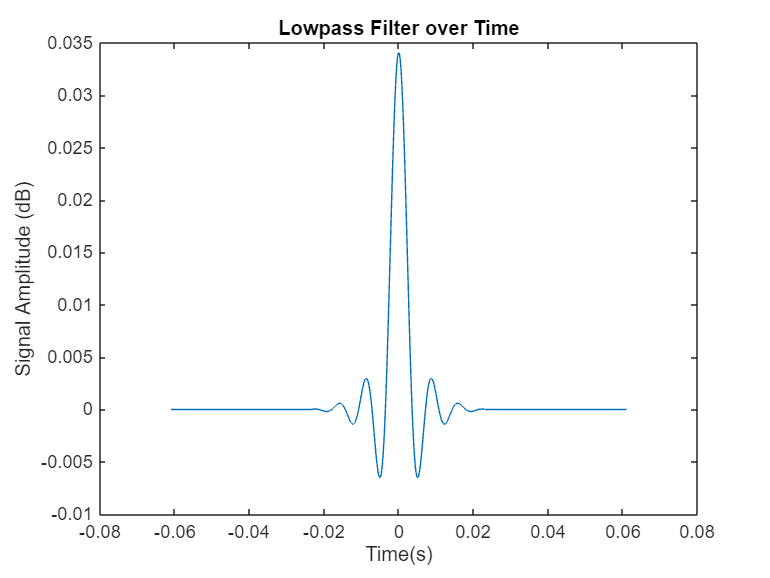

%% 

x_d_fil = lowpass(x_d,100,Fs,'Steepness',0.99);
%% 

lowpass_filter = lowpass([zeros([500 1]) ; 1 ; zeros([500 1])],100,Fs,'Steepness',0.99);
t_sp = (0:length(lowpass_filter)-1)'/Fs - ((length(lowpass_filter)-1)/Fs)/2;
plot(t_sp, lowpass_filter)
title("Lowpass Filter over Time")
xlabel("Time(s)")
ylabel("Signal Amplitude (dB)")

X =    0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i


f = 1.0e+04 *

   -2.5736   -2.5685   -2.5633   -2.5582   -2.5530   -2.5479   -2.5427   -2.5376   -2.5325   -2.5273   -2.5222   -2.5170   -2.5119   -2.5067   -2.5016   -2.4965   -2.4913   -2.4862   -2.4810   -2.4759   -2.4708   -2.4656   -2.4605   -2.4553   -2.4502   -2.4450   -2.4399   -2.4348   -2.4296   -2.4245   -2.4193   -2.4142   -2.4090   -2.4039   -2.3988   -2.3936   -2.3885   -2.3833   -2.3782   -2.3731   -2.3679   -2.3628   -2.3576   -2.3525   -2.3473   -2.3422   -2.3371   -2.3319   -2.3268   -2.3216


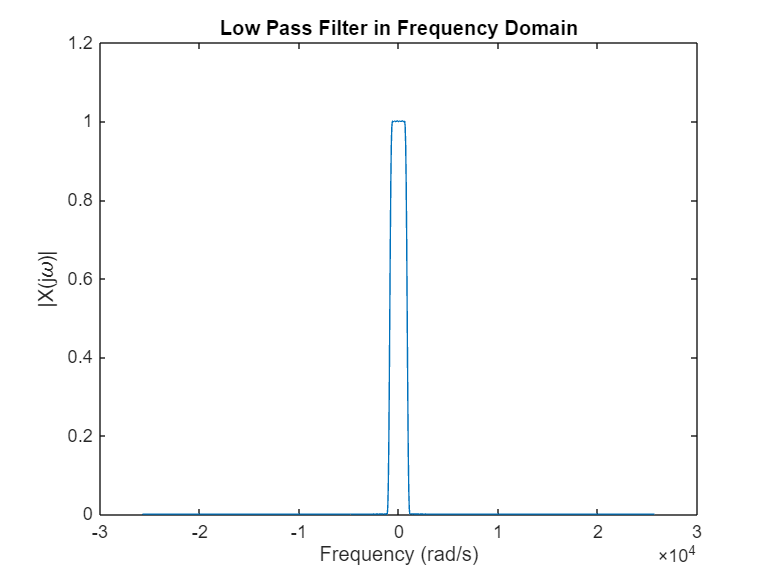

f = 1.0e+04 *

   -2.5736   -2.5685   -2.5633   -2.5582   -2.5530   -2.5479   -2.5427   -2.5376   -2.5325   -2.5273   -2.5222   -2.5170   -2.5119   -2.5067   -2.5016   -2.4965   -2.4913   -2.4862   -2.4810   -2.4759   -2.4708   -2.4656   -2.4605   -2.4553   -2.4502   -2.4450   -2.4399   -2.4348   -2.4296   -2.4245   -2.4193   -2.4142   -2.4090   -2.4039   -2.3988   -2.3936   -2.3885   -2.3833   -2.3782   -2.3731   -2.3679   -2.3628   -2.3576   -2.3525   -2.3473   -2.3422   -2.3371   -2.3319   -2.3268   -2.3216


X =    0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
   0.0000 - 0.0000i
   0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 + 0.0000i





[f, X] = make_frequency_domain_plot(Fs, lowpass_filter, "Low Pass Filter")

soundsc(x_d_fil, Fs)

%% 
t_special2 = (1:1:length(x_d_fil))/Fs

t_special2 =     0.0001    0.0002    0.0004    0.0005    0.0006    0.0007    0.0009    0.0010    0.0011    0.0012    0.0013    0.0015    0.0016    0.0017    0.0018    0.0020    0.0021    0.0022    0.0023    0.0024    0.0026    0.0027    0.0028    0.0029    0.0031    0.0032    0.0033    0.0034    0.0035    0.0037    0.0038    0.0039    0.0040    0.0042    0.0043    0.0044    0.0045    0.0046    0.0048    0.0049    0.0050    0.0051    0.0052    0.0054    0.0055    0.0056    0.0057    0.0059    0.0060    0.0061


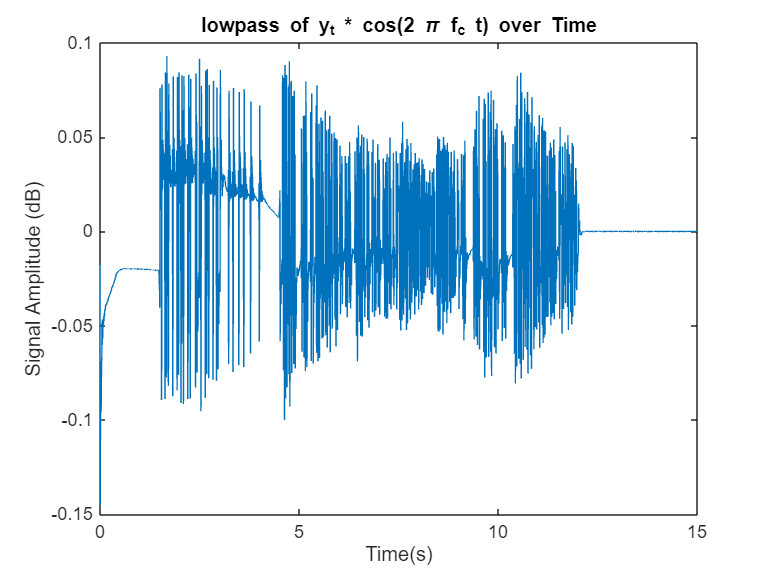

plot(t_special2, x_d_fil)
title("lowpass of y_t * cos(2 \pi f_c t) over Time")
xlabel("Time(s)")
ylabel("Signal Amplitude (dB)")

X = 1.0e+02 *

  -0.0001 - 0.0000i
  -0.0001 + 0.0000i
  -0.0001 - 0.0000i
  -0.0001 + 0.0000i
  -0.0001 + 0.0000i
  -0.0001 - 0.0000i
  -0.0001 + 0.0000i
  -0.0001 + 0.0000i
  -0.0001 + 0.0000i
  -0.0001 - 0.0000i


f = 1.0e+04 *

   -2.5736   -2.5736   -2.5735   -2.5735   -2.5734   -2.5734   -2.5733   -2.5733   -2.5733   -2.5732   -2.5732   -2.5731   -2.5731   -2.5730   -2.5730   -2.5730   -2.5729   -2.5729   -2.5728   -2.5728   -2.5728   -2.5727   -2.5727   -2.5726   -2.5726   -2.5725   -2.5725   -2.5725   -2.5724   -2.5724   -2.5723   -2.5723   -2.5723   -2.5722   -2.5722   -2.5721   -2.5721   -2.5720   -2.5720   -2.5720   -2.5719   -2.5719   -2.5718   -2.5718   -2.5717   -2.5717   -2.5717   -2.5716   -2.5716   -2.5715


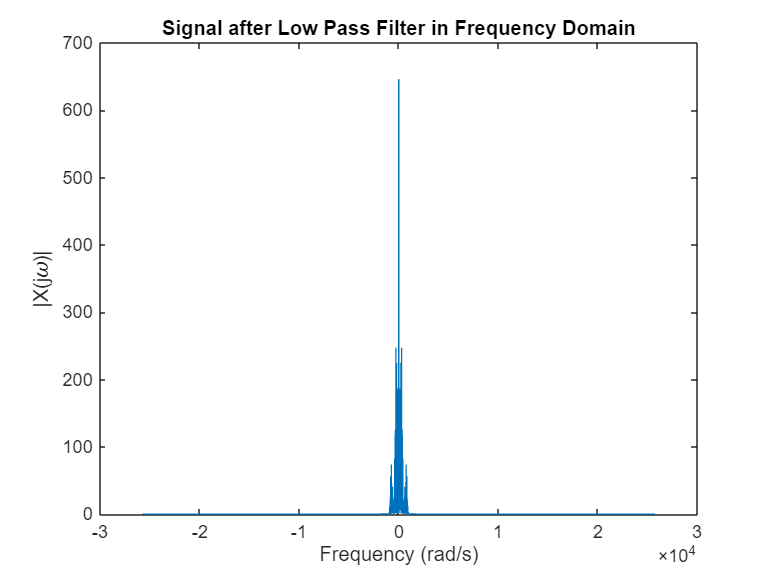

f = 1.0e+04 *

   -2.5736   -2.5736   -2.5735   -2.5735   -2.5734   -2.5734   -2.5733   -2.5733   -2.5733   -2.5732   -2.5732   -2.5731   -2.5731   -2.5730   -2.5730   -2.5730   -2.5729   -2.5729   -2.5728   -2.5728   -2.5728   -2.5727   -2.5727   -2.5726   -2.5726   -2.5725   -2.5725   -2.5725   -2.5724   -2.5724   -2.5723   -2.5723   -2.5723   -2.5722   -2.5722   -2.5721   -2.5721   -2.5720   -2.5720   -2.5720   -2.5719   -2.5719   -2.5718   -2.5718   -2.5717   -2.5717   -2.5717   -2.5716   -2.5716   -2.5715


X = 1.0e+02 *

  -0.0001 - 0.0000i
  -0.0001 + 0.0000i
  -0.0001 - 0.0000i
  -0.0001 + 0.0000i
  -0.0001 + 0.0000i
  -0.0001 - 0.0000i
  -0.0001 + 0.0000i
  -0.0001 + 0.0000i
  -0.0001 + 0.0000i
  -0.0001 - 0.0000i




[f, X] = make_frequency_domain_plot(Fs, x_d_fil, "Signal after Low Pass Filter")

soundsc(x_d_fil, Fs)


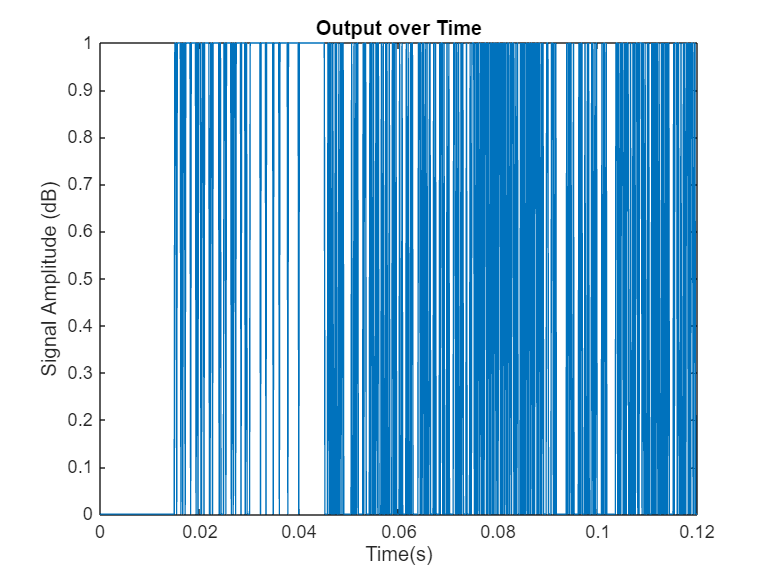

per = 100; 

mid_idx = (per/2):per:length(x_d_fil); % middle of each bit
s_vals = x_d_fil(mid_idx); % sampled values/bit
d_bit = s_vals > 0; % pos is 1 neg is 0

tot_bits = msg_length*8; % total bits

x_d = d_bit(1:tot_bits); % cut off extra bits at the end
t = (0:length(x_d)-1)'/Fs;
plot(t, x_d)
title("Output over Time")
xlabel("Time(s)")
ylabel("Signal Amplitude (dB)")

X = 1.0e+02 *

   0.1700 + 0.0000i
  -0.0233 + 0.0653i
  -0.1364 - 0.0165i
   0.0631 - 0.0427i
   0.1598 + 0.0946i
  -0.0897 + 0.0899i
   0.0387 + 0.0213i
  -0.0175 + 0.0243i
  -0.3124 + 0.1310i
  -0.1172 - 0.1346i


f =  -257.3593 -256.8362 -256.3131 -255.7900 -255.2669 -254.7438 -254.2207 -253.6977 -253.1746 -252.6515 -252.1284 -251.6053 -251.0822 -250.5591 -250.0360 -249.5130 -248.9899 -248.4668 -247.9437 -247.4206 -246.8975 -246.3744 -245.8513 -245.3282 -244.8052 -244.2821 -243.7590 -243.2359 -242.7128 -242.1897 -241.6666 -241.1435 -240.6205 -240.0974 -239.5743 -239.0512 -238.5281 -238.0050 -237.4819 -236.9588 -236.4358 -235.9127 -235.3896 -234.8665 -234.3434 -233.8203 -233.2972 -232.7741 -232.2510 -231.7280


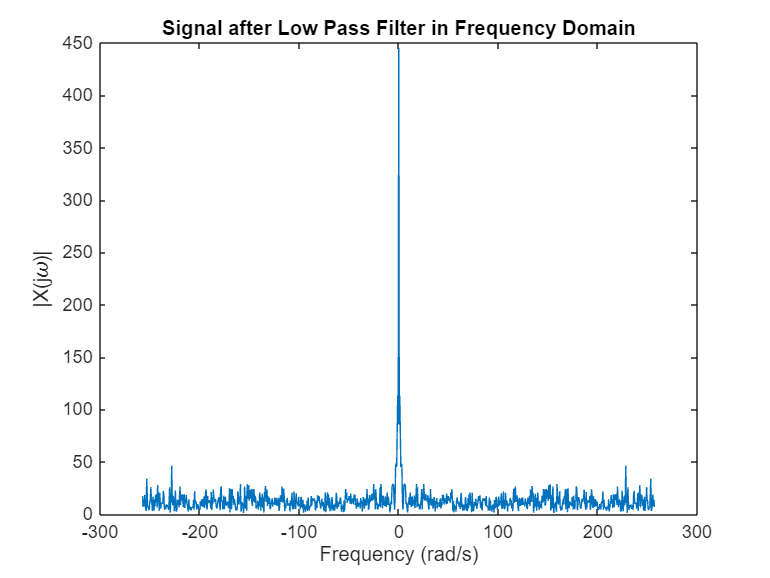

f =  -257.3593 -256.8362 -256.3131 -255.7900 -255.2669 -254.7438 -254.2207 -253.6977 -253.1746 -252.6515 -252.1284 -251.6053 -251.0822 -250.5591 -250.0360 -249.5130 -248.9899 -248.4668 -247.9437 -247.4206 -246.8975 -246.3744 -245.8513 -245.3282 -244.8052 -244.2821 -243.7590 -243.2359 -242.7128 -242.1897 -241.6666 -241.1435 -240.6205 -240.0974 -239.5743 -239.0512 -238.5281 -238.0050 -237.4819 -236.9588 -236.4358 -235.9127 -235.3896 -234.8665 -234.3434 -233.8203 -233.2972 -232.7741 -232.2510 -231.7280


X = 1.0e+02 *

   0.1700 + 0.0000i
  -0.0233 + 0.0653i
  -0.1364 - 0.0165i
   0.0631 - 0.0427i
   0.1598 + 0.0946i
  -0.0897 + 0.0899i
   0.0387 + 0.0213i
  -0.0175 + 0.0243i
  -0.3124 + 0.1310i
  -0.1172 - 0.1346i



[f, X] = make_frequency_domain_plot(Fs/100, x_d, "Signal after Low Pass Filter")

%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

soundsc(x_d*1.00, Fs)
% convert to a string assuming that x_d is a vector of 1s and 0s
% representing the decoded bits.
BitsToString(x_d)

ans = 'The answer to the Ultimate Question of Life, the Universe, and Everything is 42. The question to the ultimate answer is ...'


function [f, X] = make_frequency_domain_plot(Fs, x, Algorithm)
    [X, f] = plot_ft_rad(x, Fs)
    title(Algorithm + ' in Frequency Domain')
end